% 0. Read Data

% Read abdomenal signals
[sig1, ~, ~] = rdsamp('/mcode/databases/a67', 1);
[sig2, ~, ~] = rdsamp('/mcode/databases/a67', 2);
[sig3, ~, ~] = rdsamp('/mcode/databases/a67', 3);
[sig4, ~, ~] = rdsamp('/mcode/databases/a67', 4);
fs=1000;

% Read annotated fetal QRS locations
fileID = fopen('setAfqrs\a67.fqrs.txt','r');
directImpulse = fscanf(fileID,'%d');
fclose(fileID);

%{
sig1 = gnegate(sig1);
sig2 = gnegate(sig2);
sig3 = gnegate(sig3);
sig4 = gnegate(sig4);
%}
X_raw = [sig1 sig2 sig3 sig4];
[ndt, ns]=size(X_raw);
machka=5;

% Plot of raw signals
%{
subplot(4,1,1);
plot(sig1)
title('raw 1')
    
subplot(4,1,2); 
plot(sig2)
title('raw 2')  

subplot(4,1,3); 
plot(sig3)
title('raw 3')
   
subplot(4,1,4); 
plot(sig4)
title('raw 4')
%}

% FFT of raw data
%{
y = fft(sig3);
n = length(sig3);       % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT
plot(f,power);
xlabel('Frequency');
ylabel('Power');
%}

% 1. Preprocessing

% Detrending
n=10;
%{
D1 = detrend(X_raw(:,1),n); % removes the nth degree polynomial trend
D2 = detrend(X_raw(:,2),n);
D3 = detrend(X_raw(:,3),n);
D4 = detrend(X_raw(:,4),n);
%}
%X_d = [D1 D2 D3 D4];
X_d = X_raw;

% Bandpass filtering
order = 2530;
[X_bp, delay_bp] = bandpassFilter(X_d,BandPassCutoff3Hz,order,0); 
% delay is not used throughout since signal is centred

% Notch filtering
X_nf = FecgNotchFilt(X_bp,fs);

% FFT of raw data
%{
y = fft(X_nf(:,3));
n = length(X_nf(:,3));  % number of samples
f = (0:n-1)*(fs/n);     % frequency range
power = abs(y).^2/n;    % power of the DFT
plot(f,power);
xlabel('Frequency');
ylabel('Power');
%}

% Impulse artefact cancellation
X_im=FecgImpArtCanc(X_nf,fs,'',0);

% Interpolation DFT
%{
n = 10; % interpolate by n times
y1 = interpft(X_im(:,1),n*length(X_im(:,1)));
y2 = interpft(X_im(:,2),n*length(X_im(:,2)));
y3 = interpft(X_im(:,3),n*length(X_im(:,3)));
y4 = interpft(X_im(:,4),n*length(X_im(:,4)));

X_interp = [y1 y2 y3 y4];
fs = n*1000;
%}
X_interp = X_im;

% Interpolation spline
%{
n=2; %intepolated n times
fs=1000;
xq = 0:1/(n*fs):((length(X_im(:,1))-1)/fs)

y1 = transpose(interp1(time,X_im(:,1),xq,'cubic'));
y2 = transpose(interp1(time,X_im(:,2),xq,'cubic'));
y3 = transpose(interp1(time,X_im(:,3),xq,'cubic'));
y4 = transpose(interp1(time,X_im(:,4),xq,'cubic'));

X_interp = [y1 y2 y3 y4]
fs = 1000*n;
%}


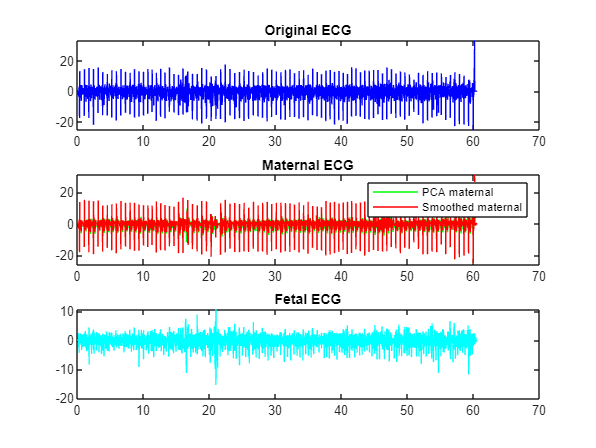

% 2. mECG cancellation
templateSize = 20;
windowTime = 0.051;

[fecg1, mecg1, ~] = cancelMecgTrial(X_interp(:,1), fs, templateSize,windowTime,0,1);

[fecg2, mecg2, ~] = cancelMecgTrial(X_interp(:,2), fs, templateSize,windowTime,0,0);
[fecg3, mecg3, ~] = cancelMecgTrial(X_interp(:,3), fs, templateSize,windowTime,0,0);
[fecg4, mecg4, delayValue] = cancelMecgTrial(X_interp(:,4), fs, templateSize,windowTime,0,0);

%}
%{
[fecg1, mecg1, ~] = cancelMecgAverage(X_interp(:,1), fs, templateSize,0,0);
[fecg2, mecg2, ~] = cancelMecgAverage(X_interp(:,2), fs, templateSize,0,0);
[fecg3, mecg3, ~] = cancelMecgAverage(X_interp(:,3), fs, templateSize,0,0);
[fecg4, mecg4, delayValue] = cancelMecgAverage(X_interp(:,4), fs, templateSize,0,1);

[fecg1, mecg1, ~] = cancelMecg(X_interp(:,1), fs, templateSize,0,0);
[fecg2, mecg2, ~] = cancelMecg(X_interp(:,2), fs, templateSize,0,0);
[fecg3, mecg3, ~] = cancelMecg(X_interp(:,3), fs, templateSize,0,0);
[fecg4, mecg4, delayValue] = cancelMecg(X_interp(:,4), fs, templateSize,0,1);
%}
%{
[fecg1, mecg1, ~] = cancelMecgMixed(X_interp(:,1), fs, templateSize,0,1);
[fecg2, mecg2, ~] = cancelMecgMixed(X_interp(:,2), fs, templateSize,0,0);
[fecg3, mecg3, ~] = cancelMecgMixed(X_interp(:,3), fs, templateSize,0,0);
[fecg4, mecg4, delayValue] = cancelMecgMixed(X_interp(:,4), fs, templateSize,0,0);
%}
%{
[fecg1, mecg1, ~] = cancelMecgCausalAverage(X_interp(:,1), fs, templateSize,0,0);
[fecg2, mecg2, ~] = cancelMecgCausalAverage(X_interp(:,2), fs, templateSize,0,0);
[fecg3, mecg3, ~] = cancelMecgCausalAverage(X_interp(:,3), fs, templateSize,0,0);
[fecg4, mecg4, delayValue] = cancelMecgCausalAverage(X_interp(:,4), fs, templateSize,0,1);
%}

% 3. ICA/Post-processing

% Try ICA for separating noise and signals of interest
Z = [fecg1, fecg2, fecg3, fecg4];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

***** Fast ICA (kurtosis) *****
Iter 001: max(1 - |<w001, w000>|) = -0.9477




ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);

% Direct impulse interpolation
%directImpulse = n*directImpulse;

%Trapezzoid
qrsM=chanelSelection(X_im,fs);

Number of detected mother QRSs= 88


Xr=FecgQRSmCanc(X_im,qrsM,fs,'Name',0);


 --------------------------------------------------------- 
Program:  FecgQRSmCanc,  record name: Name
Number of QRSs= 88
RR mean= 6.857778e-01,  stdev=1.979823e-02
is=1, pownds=0.948806
is=2, pownds=0.948806
is=3, pownds=0.948806
is=4, pownds=0.948806


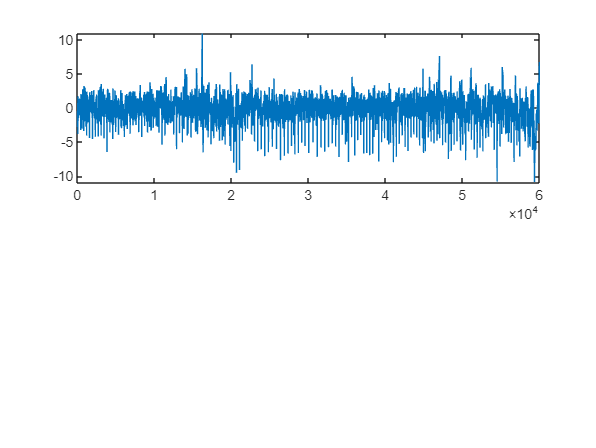

plot(Xr(:,1))

% 4. F1 calculation
comparedSignal = fecg1;
[f1, estimatedR] = compareDirectTrial(comparedSignal, directImpulse,0,fs);
f1=f1

f1 = 0.1753

% RLS adaptive filter
d = X_im(:,4);
x = transpose(mecg1(201:length(mecg1)-401));
taps = 20;
fFactor = 0.995;
rls= dsp.RLSFilter(taps,"ForgettingFactor",fFactor);
[y,e] = rls(x,d);
w = rls.Coefficients;
plot(e);

% Try an adaptive LMS filter

l=30; 
mu=0.01;
lms = dsp.LMSFilter('Length',l,'StepSize',mu,'Method','Normalized LMS');
mecg1 = transpose(mecg1);
[y,e,w] = lms(mecg1(delayValue:length(X_im(:,1))+delayValue-1),X_im(:,1));
plot(y)
plot(e)


% Adaptive Filter
%{
d = X_im(:,1);
x = transpose(mecg1(201:length(mecg1)-301));
lms = dsp.LMSFilter;
[y,err,wts] = lms(x,d);
plot(err)
%}


%Wavelet Fun
%{
[swa1,swd1] = swt(fecg1(201:(length(fecg1)-369)),7,'db1');
[swa2,swd2] = swt(fecg2(201:(length(fecg2)-369)),7,'db1');
[swa3,swd3] = swt(fecg3(201:(length(fecg3)-369)),7,'db1');
[swa4,swd4] = swt(fecg4(201:(length(fecg4)-369)),7,'db1');
sLen = 60000;
swd11 = transpose(swd1(5,:));
swa11 = transpose(swa1(5,:));
swd22 = transpose(swd2(5,:));
swa22 = transpose(swa2(5,:));
swd33 = transpose(swd3(5,:));
swa33 = transpose(swa3(5,:));
swd44 = transpose(swd4(5,:));
swa44 = transpose(swa4(5,:));

%subplot(2,1,1)

plot(swa11)
xlim([0 sLen])
title('Level 7 Approximation coefficients')
subplot(2,1,2)
plot(swd11)
xlim([0 sLen])
title('Level 7 Detail coefficients')

Z = [swa11, swa22, swa33, swa44];
Z = transpose(Z);
r = 4;
[Zica, W, T, mu] = fastICA(Z,r);

ica1 = Zica(1,:);
ica2 = Zica(2,:);
ica3 = Zica(3,:);
ica4 = Zica(4,:);

comparedSignal = swa33;
[f1, estimatedR] = compareDirect(comparedSignal, directImpulse, 0, fs);
f1=f1
%}

% Plot

% Plot ica results
%{
subplot(4,1,1);
plot(ica1)
title('ica 1')

subplot(4,1,2);
plot(ica2)
title('ica 2')

subplot(4,1,3);
plot(ica3)
title('ica 3')

subplot(4,1,4);
plot(ica4)
title('ica 4')

%}
% mECG plots
%{
subplot(4,1,1);
plot(mecg1)
title('mECG 1')
    
subplot(4,1,2); 
plot(mecg2)
title('mECG 2')  

subplot(4,1,3); 
plot(mecg3)
title('mECG 3')
   
subplot(4,1,4); 
plot(mecg4)
title('mECG 4')
%}

% fECG plots
%{
subplot(4,1,1);
plot(fecg1)
title('fECG 1')
    
subplot(4,1,2); 
plot(fecg2)
title('fECG 2')  

subplot(4,1,3); 
plot(fecg3)
title('fECG 3')
   
subplot(4,1,4); 
plot(fecg4)
title('fECG 4')
%}

%{
subplot(4,1,1);
plot(X_im(:,1))
title('Imp 1')
    
subplot(4,1,2); 
plot(X_im(:,2))
title('Imp 2')  

subplot(4,1,3); 
plot(X_im(:,3))
title('Imp 3')
   
subplot(4,1,4); 
plot(X_im(:,4))
title('Imp 4')
%}
